# Example: Iterative fitting for multiple provinces in China  (22-Jan-2020 - )

In this example, the generalized SEIR model is automatically fitted to multiple provinces in China. As in the previous examples, I am taking some data, collected into DATA.mat from John Hopkins university [1]. To keep the computation as short as possible, the option "iter" is removed using an optional argument.

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 02-Jun-2020




Location = 'China';


try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1);
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1);
    indD = find(contains(tableDeaths.CountryRegion,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));    
end

% disp(tableRecovered(indR,1:2))
disp(tableConfirmed(indC,1:2))

     ProvinceState      CountryRegion
    ________________    _____________

    "Anhui"                "China"   
    "Beijing"              "China"   
    "Chongqing"            "China"   
    "Fujian"               "China"   
    "Gansu"                "China"   
    "Guangdong"            "China"   
    "Guangxi"              "China"   
    "Guizhou"              "China"   
    "Hainan"               "China"   
    "Hebei"                "China"   
    "Heilongjiang"         "China"   
    "Henan"                "China"   
    "Hong Kong"            "China"   
    "Hubei"                "China"   
    "Hunan"                "China"   
    "Inner Mongolia"       "China"   
    "Jiangsu"              "China"   
    "Jiangxi"              "China"   
    "Jilin"                "China"   
    "Liaoning"             "China"   
    "Macau"                "China"   
    "Ningxia"              "China"   
    "Qinghai"      

% disp(tableDeaths(indD,1:2))

% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases


## Iterative application of fit_SEIQRDP

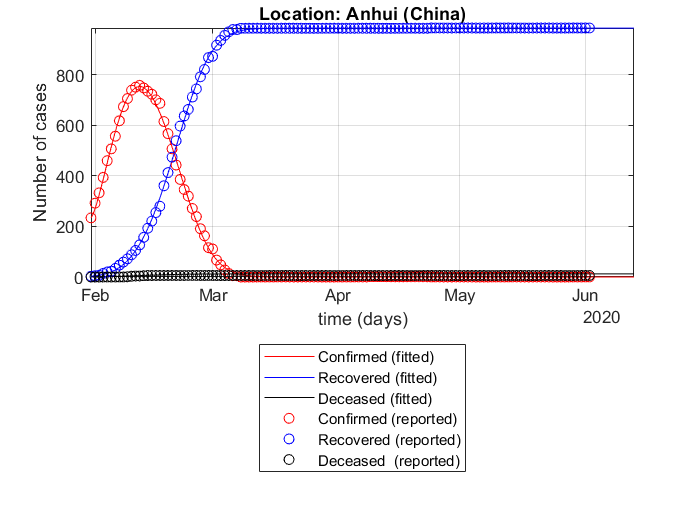

Elapsed time is 4.205738 seconds.


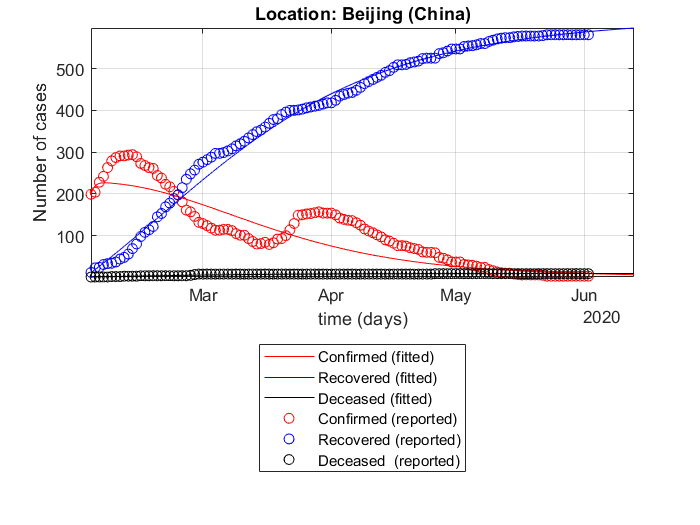

Elapsed time is 6.715763 seconds.


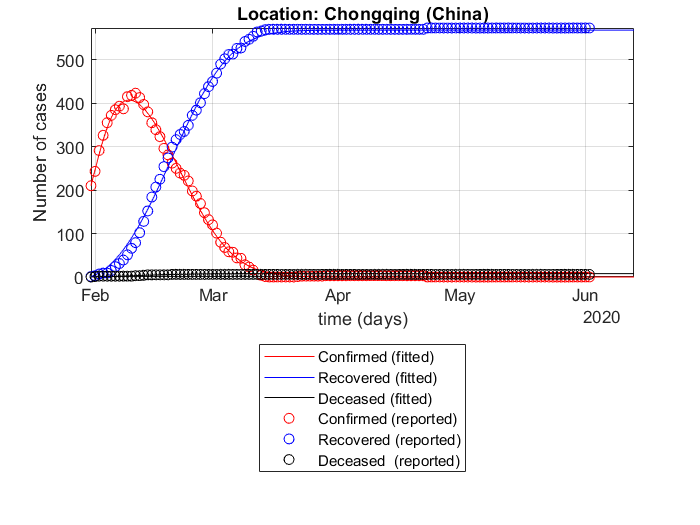

Elapsed time is 19.663889 seconds.


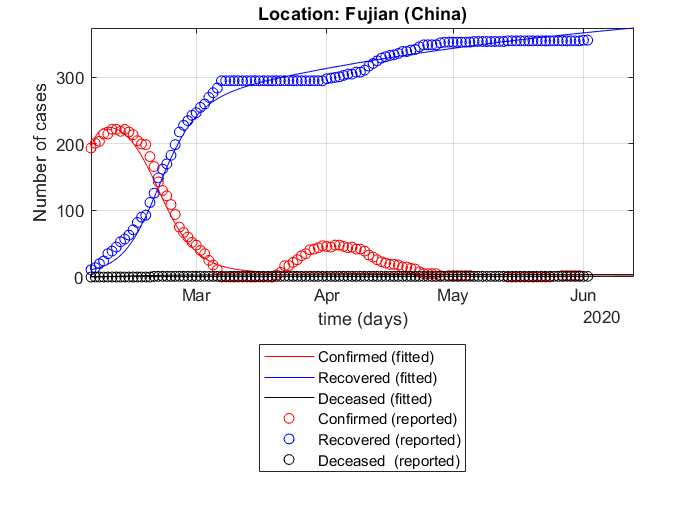

Elapsed time is 4.998438 seconds.


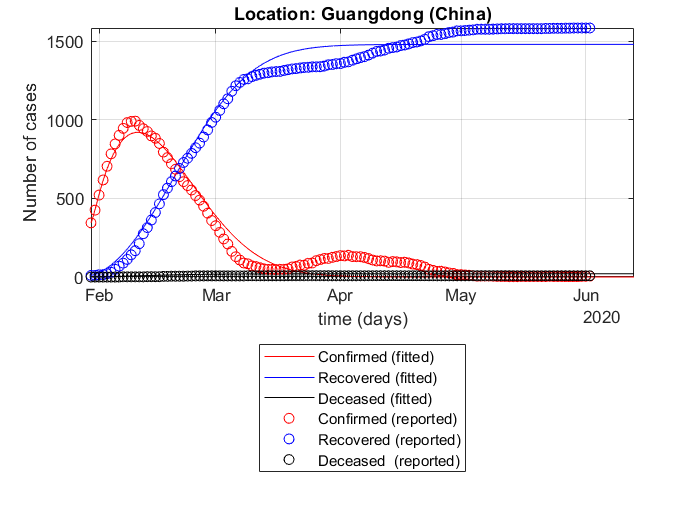

Elapsed time is 9.174501 seconds.


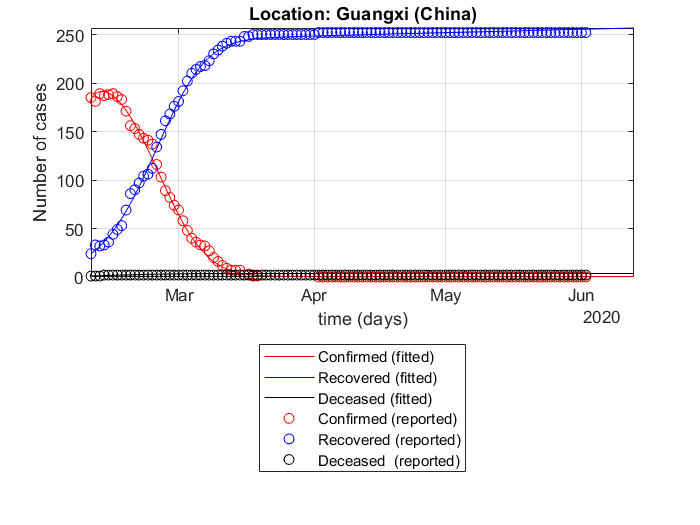

Elapsed time is 12.867088 seconds.


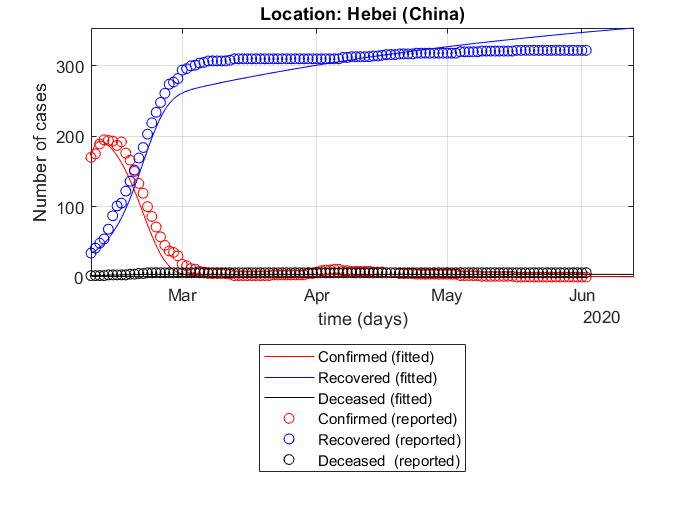

Elapsed time is 5.970406 seconds.


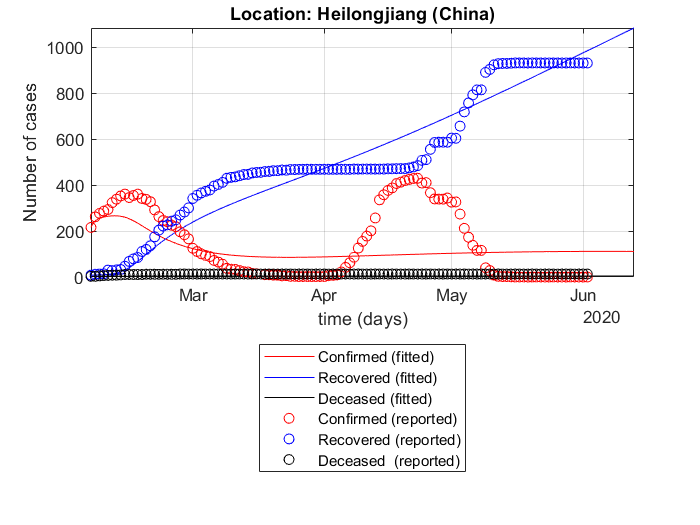

Elapsed time is 11.160032 seconds.


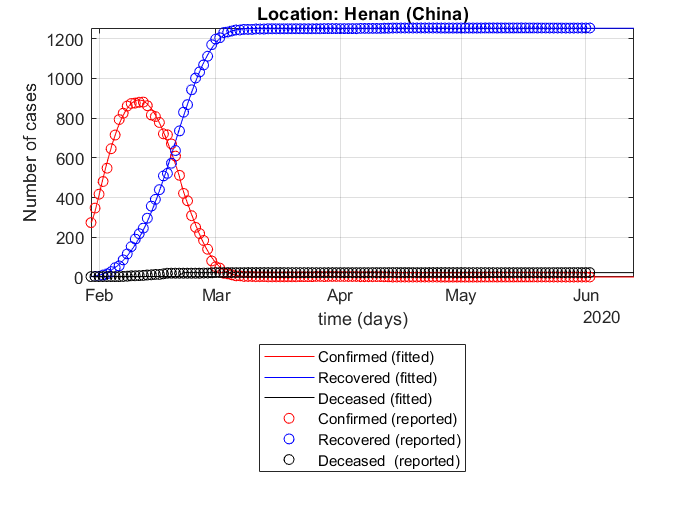

Elapsed time is 10.024783 seconds.


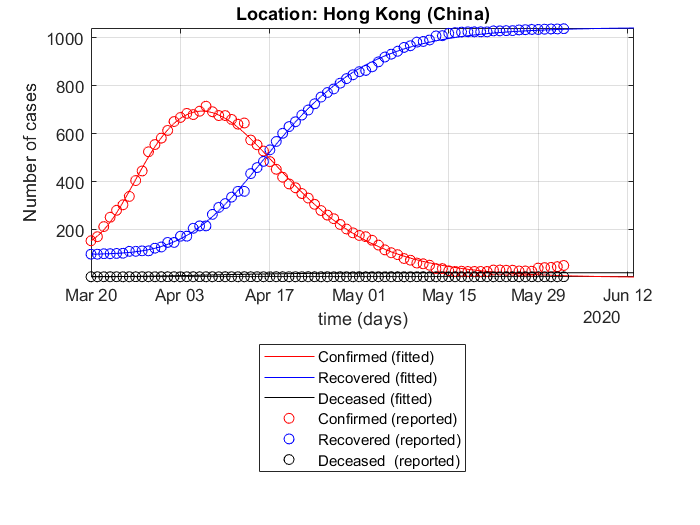

Elapsed time is 10.568637 seconds.


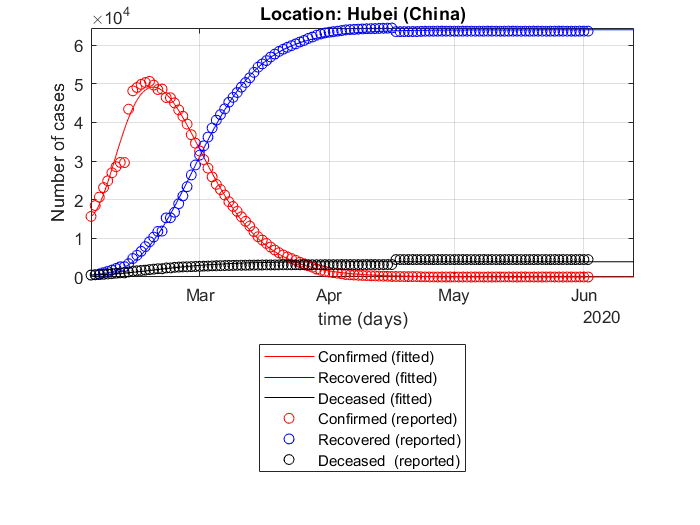

Elapsed time is 10.194688 seconds.


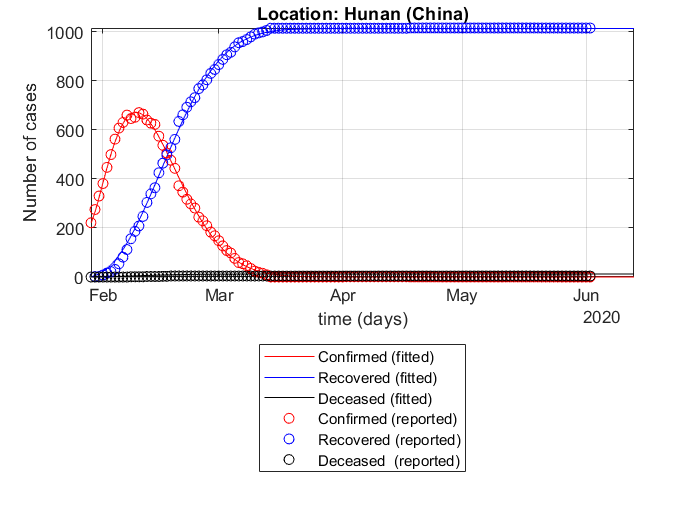

Elapsed time is 8.726665 seconds.


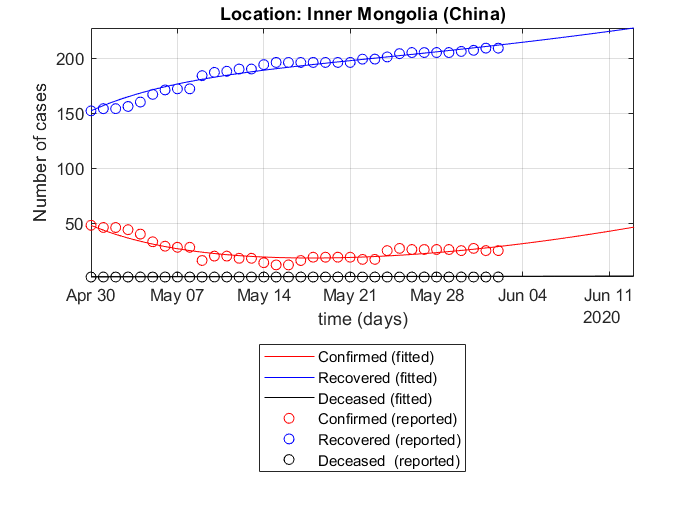

Elapsed time is 6.449693 seconds.


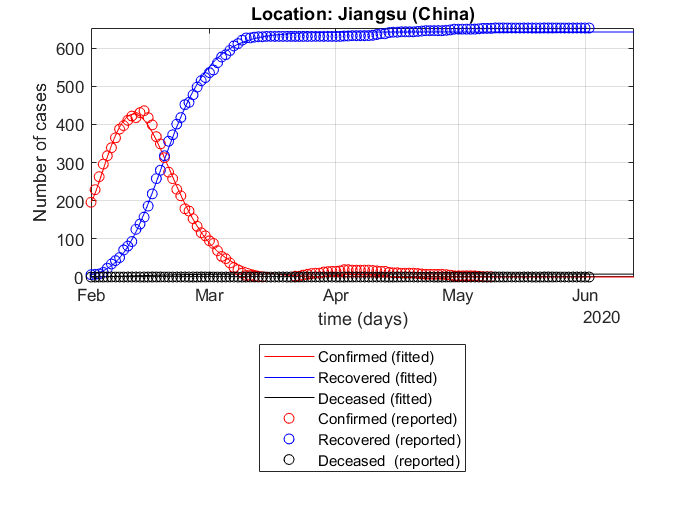

Elapsed time is 4.475061 seconds.


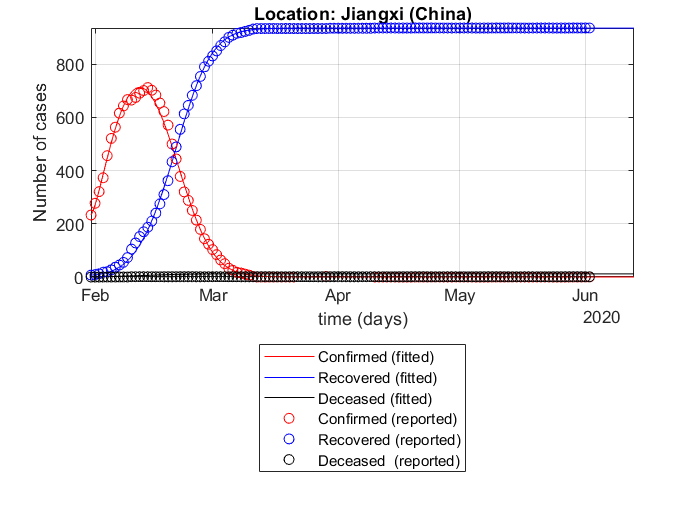

Elapsed time is 16.450421 seconds.


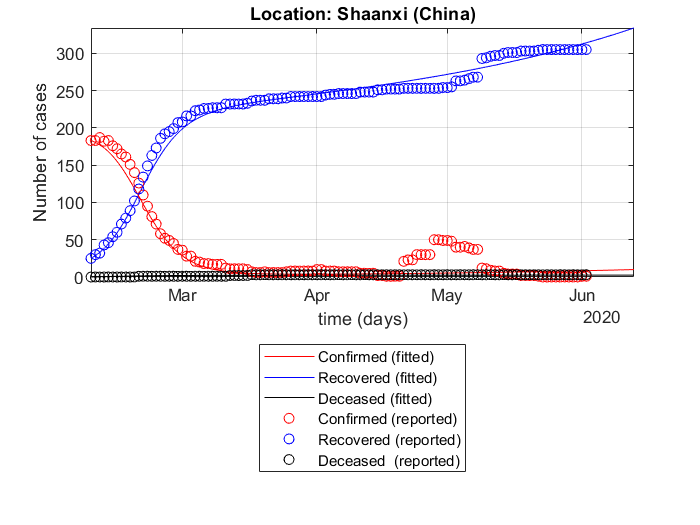

Elapsed time is 6.793378 seconds.


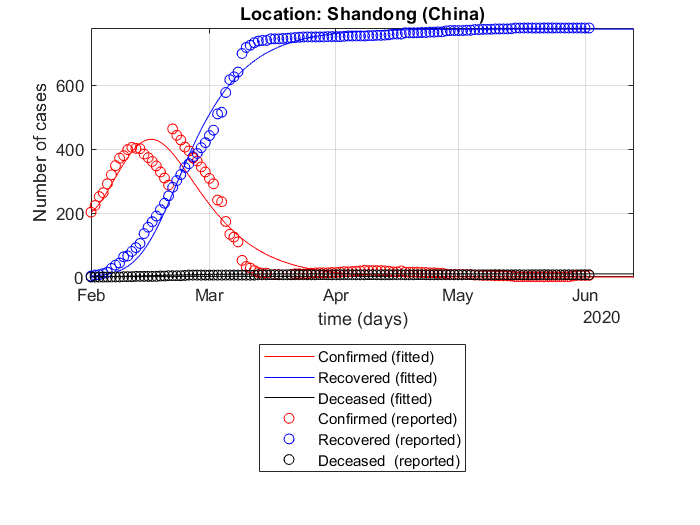

Elapsed time is 4.925014 seconds.


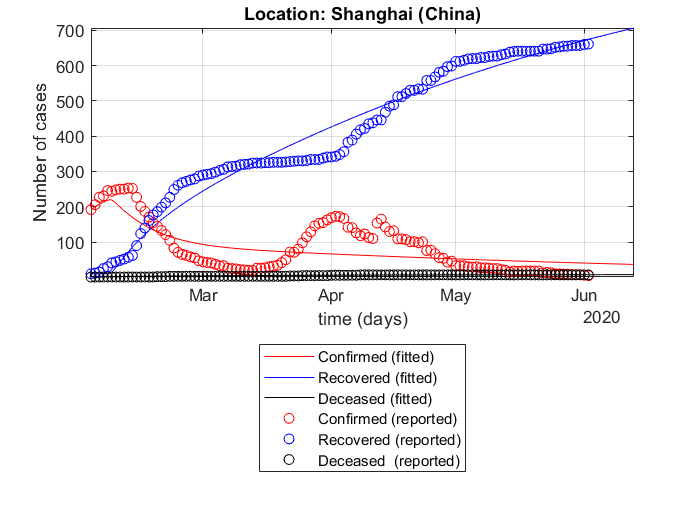

Elapsed time is 4.284221 seconds.


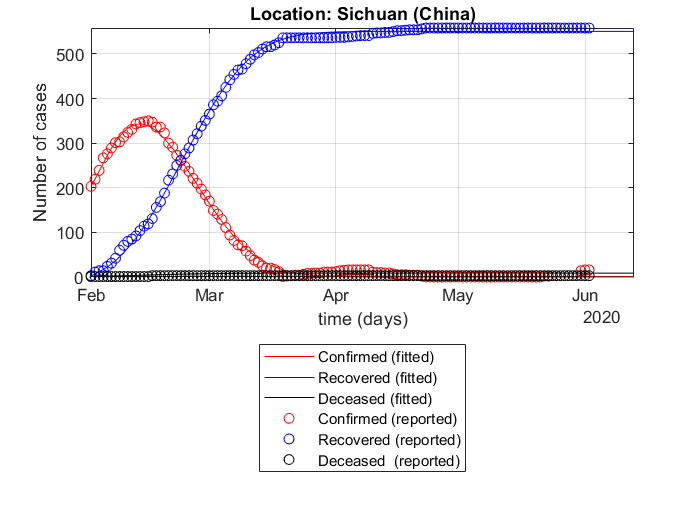

Elapsed time is 17.748082 seconds.


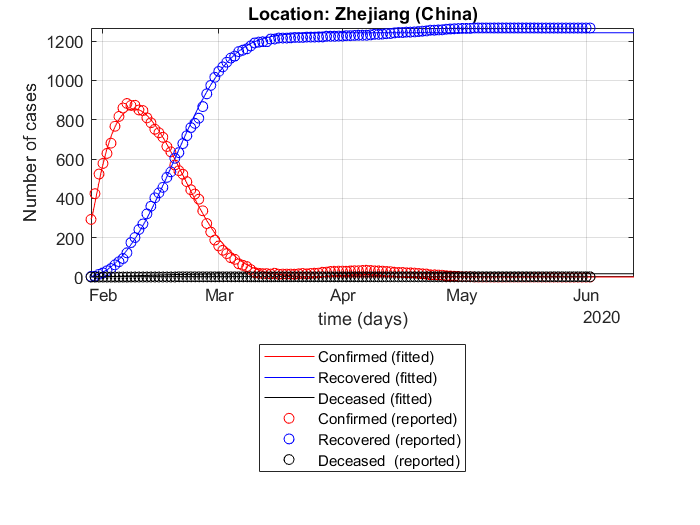

Elapsed time is 9.321220 seconds.


timeRef = time; % Used in the loop only

        
        
for ii = 1:min([numel(indR),numel(indC),numel(indD)])
    Recovered = table2array(tableRecovered(indR(ii),5:end));
    Deaths = table2array(tableDeaths(indD(ii),5:end));
    Confirmed = table2array(tableConfirmed(indC(ii),5:end));
    minNum= max(200,round(0.2*max(Confirmed)));
    
    
    % Warning! a dummy value of Npop is used here. If you want a realistic
    % value for beta, you need to specify the correct value for Npop
     Npop= 30e6; % population (It affects the values of the parameters)
     
     
    % Remove case where only few infectious are recorded (to avoid bad
    % initial conditions)
    Recovered(Confirmed<=minNum)=[];
    Deaths(Confirmed<=minNum)=[];
    time = timeRef; % trick to avoid reloading the variable "time" at each new loop
    time(Confirmed<=minNum)= [];
    Confirmed(Confirmed<=minNum)=[];
    Active = Confirmed-Recovered-Deaths;
    Active(Active<0) = 0; % No negative number possible
    [~,indMin] = min(Active);
    % The fitting is only applied if enough data is collected (that is why
    % I use the case of China)
    if numel(Confirmed)>30% quick and dirty way to select high-quality dataset (more than 30 days)
        tic
        
        % Definition of the first estimates for the parameters
        alpha_guess = 0.06; % protection rate
        beta_guess = 0.8; % Infection rate
        LT_guess = 5; % latent time in days
        Q_guess = 0.5; % rate at which infectious people enter in quarantine
        lambda_guess = [0.01,0.01,10]; % recovery rate
        kappa_guess = [0.005,0.005,10]; % death rate
        
        guess = [alpha_guess,beta_guess,1/LT_guess, Q_guess,lambda_guess,kappa_guess];
        
        % Initial conditions
        Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
        I0 = 0.2*Q0; % Initial number of infectious cases. Unknown but unlikely to be zero.
        E0 = Q0; % Initial number of exposed cases. Unknown but unlikely to be zero.
        R0 = Recovered(1);
        D0 = Deaths(1);
       

        [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
            fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off');
        
%         disp(alpha1);
%         disp(beta1);
%         disp(gamma1)
%         disp(delta1)
%         disp(Lambda1);
%         disp(Kappa1)
        
        dt = 1/24; % time step
        time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(10)));
        N = numel(time1);
        t = [0:N-1].*dt;
        
        
        % Call of the function SEIQRDP.m with the fitted parameters
        [S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,...
            Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);
        
        figure
               
        semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
        hold on
        semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
        % ylim([0,1.1*Npop])
        ylabel('Number of cases')
        xlabel('time (days)')
        leg = {'Confirmed (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Confirmed (reported)','Recovered (reported)','Deceased  (reported)'};
        legend(leg{:},'location','southoutside');
        set(gcf,'color','w')
        
        %%% title %%%
        subLoc = char(table2array(tableRecovered(indR(ii),1)));
        Loc = char(table2array(tableRecovered(indR(ii),2)));
        title(['Location: ',subLoc,' (',Loc,')'])
        %%%%%%%%%%%%%
        
        grid on
        axis tight
        set(gca,'yscale','lin')
        toc
        
        pause(1)
    end
end